# Robust Simple Inverted Pendulum: Mathematical Modelling & $H_{\infty}$ Synthesis

Course: INEL 5595

Professor: Dr. Gerson Beauchamp Báez

Author: Marcos R. Pesante Colón

Last Edited: Dec/04/2022

What follows is the derivation of three Multiple-Input, Multiple-Output (MIMO) mathematical models for the simple inverted pendulum:

- **Nonlinear Model:** Uses the Euler-Lagrange method to determine the dynamic equations. MATLAB then helps to find the derivative of the state vector $\dot{x}(t)$ in terms of nonlinear combinations of the state variables.

- **Linearized Model: **The nonlinear model is linearized around an operating point.

- **Uncertain Linear Model:** System parameters in linearized model are substituted with uncertainty.

For this purpose, symbolic variables are declared, then the dynamic equations are determined using the Euler-Lagrange method, these dynamic equations are linearized around an operating point, and finally their parameters are substituted using multiple `ureal` parameters as defined by the manuals.

## 0) Initial Setup

Some cleanup tasks are executed in order to prevent name collissions, and overall just to make the operation of this program as consistent as possible. We also configure the live editor's behavior while handling symbolic expressions.

close all;                              % Close any open plots
clear;                                  % Clear all the variables in the workspace
clc;                                    % Clear the command window

sympref("AbbreviateOutput", false);     % Prevent the live editor from simplifying symbolic expressions

## 1) Variable Declaration and Documentation

System parameters are declared as symbolic variables to be used later in the code. They are documented as they are declared to make it clear what their purpose is. System disturbances in the form of $F_d(t)$ (disturbance force) and $\tau_d(t)$ (disturbance torque) are now included as part of the model.

Important variables like state vector and others are also declared in this section as symbolic variables.

syms t positive real;       % time
syms s complex;             % complex frequency
syms g positive real;       % Gravitational Acceleration

syms R_m positive real;     % Motor armature Resistance
syms K_t positive real;     % Motor torque Constant
syms eta_m positive real;   % Motor Efficiency
syms K_m positive real;     % Back-EMF Constant
syms J_m positive real;     % Rotor Moment of Intertia
syms K_g positive real;     % Planetary Gearbox Gear Ratio
syms eta_g positive real;   % Planetary Gearbox Efficiency
syms M positive real;       % IP02 Cart Including Extra Weight
syms M_c positive real;     % Lumped Mass of the Cart System, including Rotor Intertia
syms r_mp positive real;    % Motor Pinion Radius
syms B_eq positive real;    % Equivalent Viscous Damping Coefficient as seen at the Motor Pinion
syms B_p positive real;     % Viscous Damping Coefficient from Pendulum Bearing
syms M_p positive real;     % Pendulum Mass (with T-fitting)
syms L_p positive real;     % Pendulum Full Length (from Pivot to Tip)
syms l_p positive real;     % Pendulum Length from Pivot to Center of Gravity
syms J_p positive real;     % Pendulum Moment of Inertia

syms V_m(t);                % Motor Armature Voltage
syms F_c(t);                % Cart Driving Force Produced by the Motor
syms F_d(t);
syms Tau_d(t);

syms x_c(t);                % Cart Linear Position
syms alpha(t);              % Pendulum Angle From the Upright Position

syms x_ref(t);
syms x_dot_ref(t);
syms alpha_ref(t);
syms alpha_dot_ref(t);


% Force as a function of Voltage. Relationship comes from formula B.9 in 
% `[7] Quanser linear Experiment #1 PV Position Control (IP01 and IP02).pdf`
F_c(t) = expand(eta_g * K_g * eta_m * K_t * (V_m(t) * r_mp - K_g * K_m * diff(x_c(t), t)) / (R_m * r_mp^2));

% State Vector x(t)
x(t) = [
    x_c(t);                 % Cart Linear Position
    alpha(t);               % Pendulum Angle from the Upright Position
    diff(x_c(t), t);        % Cart Linear Velocity
    diff(alpha(t), t);      % Pendulum Angular Velocity
];
x_num = sym('x', size(x(t)));    % Symbolic state vector only with numbers

% Output Vector
y(t) = [
    x_c(t);                     % Cart Linear Position Measurement
    alpha(t);                 % Pendulum Angle Measurement from the Upright Position
];

% Input Vector
u(t) = [
    F_d(t);
    Tau_d(t);
    V_m(t)
];

% Generalized Positions Vector
q(t) = [
    x_c(t);                 % Cart Linear Position
    alpha(t);               % Pendulum Angle from the Upright Position
];

% Generaized Forces Vector
f(t) = [
    F_c(t) - B_eq * diff(x_c(t), t) - F_d(t);    % Linear forces acting over the cart
    -B_p * diff(alpha(t), t) - Tau_d(t)          % Angular forces acting over the pendulum
];

% Variable that will help while using the `functionalJacobian` method
all_functions(t) = [
    q(t);
    diff(q(t), t);
    diff(q(t), t, 2); 
    u(t)
];

syms x_c_0 positive real;   % Initial Cart Position (at t=0)
syms alpha_0 positive real; % Initial Pendulum Angle (at t=0)

operating_point = [
    x_c_0;
    0;
    0;
    0
];

## 2) Euler-Lagrange Derivation

The Euler-Lagrange method is used to find the system dynamic equations. By defining the Lagrangian $L = K - U$ where $K$ is the sum of the kinetic energies and $U$ the potential energies of the system:


$$\frac{d}{d t}\left( \frac{\partial L}{\partial \dot{q}(t)} \right) - \frac{\partial L}{\partial q(t)} = f(t)$$


Finally, the dynamic equations are simplified and displayed. I encourage checking the derivaton of these energies to make sure that MATLAB is running these computations as expected. In addition, it might give insight as to how the simple inverted pendulum system works.

% Absolute x-coordinate of the pendulum center of gravity
x_p(t) = x_c(t) - l_p * sin(alpha(t));
% Absolute y-coordinate of the pendulum center of gravity
y_p(t) = 0 + l_p * cos(alpha(t));

% Kinetic Energies
K = ... Kinetic Energy of the Motorized Cart
    1/2 * M * diff(x_c(t), t)^2 + ...
    ... Kinetic Energy due to Cart's DC motor
    1/2 * J_m * K_g^2 / r_mp^2 * diff(x_c(t), t)^2 + ...
    ... Kinetic Energy of Pendulum's Translational Kinetic Energy
    1/2 * M_p * (diff(x_p(t), t)^2 + diff(y_p(t), t)^2) + ...
    ... Pendulum's Rotational Kinetic Energy
    1/2 * J_p * diff(alpha(t), t)^2;

K = enhancedSimplify(expand(K), x(t), 100, 2);
K = subs(K, M/2 + J_m * K_g^2 / (2*r_mp^2), M_c/2) % Extra step used to simplify the modelling later on

$$K = \left(\frac{M_{c}}{2}+\frac{M_{p}}{2}\right)\,{\left(\frac{\partial }{\partial t}x_{c}\left(t\right)\right)}^{2}+\left(\frac{M_{p}\,{l_{p}}^{2}}{2}+\frac{J_{p}}{2}\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}-M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}x_{c}\left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)$$

% Potential Energies
U = M_p * g * l_p * cos(alpha(t));
U = enhancedSimplify(expand(U), x(t), 100, 2)

$$U = M_{p}\,g\,l_{p}\,\cos\left(\alpha \left(t\right)\right)$$

% Compute Lagrangian
L = K - U;
L = enhancedSimplify(expand(L), x(t), 100, 2)

$$L = \left(\frac{M_{c}}{2}+\frac{M_{p}}{2}\right)\,{\left(\frac{\partial }{\partial t}x_{c}\left(t\right)\right)}^{2}+\left(-M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right)\right)\,\frac{\partial }{\partial t}x_{c}\left(t\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)+\left(\frac{M_{p}\,{l_{p}}^{2}}{2}+\frac{J_{p}}{2}\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}-M_{p}\,g\,l_{p}\,\cos\left(\alpha \left(t\right)\right)$$

% d(∂L/∂q_dot(t))/dt - ∂L/∂q(t)
dynamic_equations = diff(functionalJacobian(L, diff(q(t), t), all_functions(t)), t) ...
    - functionalJacobian(L, q(t), all_functions(t));
% Finish forming the dynamic equations and simplify the result
dynamic_equations = enhancedSimplify(row2col(dynamic_equations) == f(t), all_functions, 100, 5)

$$dynamic\_equations = \left(\begin{array}{c} \left(M_{p}\,l_{p}\,\sin\left(\alpha \left(t\right)\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}+\left(M_{c}+M_{p}\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)+\left(-M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)=\left(-B_{\mathrm{eq}}-\frac{{K_{g}}^{2}\,K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}}{R_{m}\,{r_{\mathrm{mp}}}^{2}}\right)\,\frac{\partial }{\partial t}x_{c}\left(t\right)-F_{d}\left(t\right)+\frac{K_{g}\,K_{t}\,\eta_{g}\,\eta_{m}}{R_{m}\,r_{\mathrm{mp}}}\,V_{m}\left(t\right)\\ B_{p}\,\frac{\partial }{\partial t}\alpha \left(t\right)+\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)+{Τ}_{d}\left(t\right)=\left(M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x_{c}\left(t\right)+M_{p}\,g\,l_{p}\,\sin\left(\alpha \left(t\right)\right) \end{array}\right)$$

## 3) Linearizing the System

By taking a couple of jacobians it is possible to linearize the nolinear system and represent it as follows:


$$\dot{x}_\delta(t) = Ax_\delta(t) + Bu_\delta(t)$$



$$y_\delta(t) = Cx_\delta(t) + Du_\delta(t)$$


The jacobians to be calculated are as follows:


$$A = \left. \frac{\partial f(x, u)}{\partial x(t)} \right\vert_{(x_0, u_0)}$$
         
$$B = \left. \frac{\partial f(x, u)}{\partial u(t)} \right\vert_{(x_0, u_0)}$$



$$C = \left. \frac{\partial g(x, u)}{\partial x(t)} \right\vert_{(x_0, u_0)}$$
        
$$D = \left. \frac{\partial g(x, u)}{\partial u(t)} \right\vert_{(x_0, u_0)}$$


At the end the characteristic polynomial is displayed. This polynomial will probably not be too useful in its symbolic form, but it will be useful later on when substituting the system parameters in it.

% The following lines make it possible to use `massMatrixForm`
for idx = 1:length(x(t))
    eval(sprintf("syms z_%d(t)", idx))
end
z(t) = row2col(arrayfun(@(idx) evalin('base', sprintf("z_%d(t)", idx)), 1:4));
z_pos(t) = subs(q(t), x(t), z(t));              % Generalized vector of positions
z_vel(t) = subs(diff(q(t), t), x(t), z(t));     % Generalized vector of velocities

tmp = subs(dynamic_equations, diff(q(t), t, 2), diff(z_vel(t), t));
tmp = subs(tmp, diff(q(t), t, 1), z_vel(t));
tmp = subs(tmp, q(t), z_pos(t));
tmp = [diff(z_pos(t), t); tmp];

% Finally determine the nonlinear model
[Mass, Function] = massMatrixForm(tmp, z(t));
Mass = subs(Mass, z(t), x(t))

$$Mass = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & M_{c}+M_{p} & -M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right)\\ 0 & 0 & -M_{p}\,l_{p}\,\cos\left(\alpha \left(t\right)\right) & M_{p}\,{l_{p}}^{2}+J_{p} \end{array}\right)$$

Function = subs(Function, z(t), x(t))

$$Function = \left(\begin{array}{c} 0\\ 0\\ \frac{K_{g}\,K_{t}\,\eta_{g}\,\eta_{m}\,V_{m}\left(t\right)}{R_{m}\,r_{\mathrm{mp}}}-\left(B_{\mathrm{eq}}+\frac{{K_{g}}^{2}\,K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}}{R_{m}\,{r_{\mathrm{mp}}}^{2}}\right)\,\frac{\partial }{\partial t}x_{c}\left(t\right)-M_{p}\,l_{p}\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}-F_{d}\left(t\right)\\ -B_{p}\,\frac{\partial }{\partial t}\alpha \left(t\right)-{Τ}_{d}\left(t\right)+M_{p}\,g\,l_{p}\,\sin\left(\alpha \left(t\right)\right) \end{array}\right)$$

nonlinear_model(t) = Mass \ Function;
nonlinear_model(t) = nonlinear_model(t) + diff(x(t), t) .* logical(nonlinear_model(t) == 0);
nonlinear_model(t) = enhancedSimplify(nonlinear_model(t), all_functions, 1000, 10)

% Replace the acceleration functions with scalars in preparation for linearization
nonlinear_model(t) = subs(nonlinear_model(t), x(t), x_num);
A = subs(functionalJacobian(nonlinear_model(t), x_num, all_functions(t)), x_num, operating_point);
A = enhancedSimplify(A, [], 100, 2)

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{{M_{p}}^{2}\,g\,{l_{p}}^{2}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} & -\frac{\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)\,\left(K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}\,{K_{g}}^{2}+B_{\mathrm{eq}}\,R_{m}\,{r_{\mathrm{mp}}}^{2}\right)}{R_{m}\,{r_{\mathrm{mp}}}^{2}\,\left(M_{c}\,\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)+J_{p}\,M_{p}\right)} & -\frac{B_{p}\,M_{p}\,l_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)}\\ 0 & \frac{M_{p}\,g\,l_{p}\,\left(M_{c}+M_{p}\right)}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} & -\frac{M_{p}\,l_{p}\,\left(K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}\,{K_{g}}^{2}+B_{\mathrm{eq}}\,R_{m}\,{r_{\mathrm{mp}}}^{2}\right)}{R_{m}\,{r_{\mathrm{mp}}}^{2}\,\left(M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)\right)} & -\frac{B_{p}\,\left(M_{c}+M_{p}\right)}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} \end{array}\right)$$

B = subs(functionalJacobian(nonlinear_model(t), u(t), all_functions(t)), x_num, operating_point);
B = enhancedSimplify(B, [], 100, 2)

$$B = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ -\frac{M_{p}\,{l_{p}}^{2}+J_{p}}{M_{c}\,\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)+J_{p}\,M_{p}} & -\frac{M_{p}\,l_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} & \frac{K_{g}\,K_{t}\,\eta_{g}\,\eta_{m}\,\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)}{R_{m}\,r_{\mathrm{mp}}\,\left(M_{c}\,\left(M_{p}\,{l_{p}}^{2}+J_{p}\right)+J_{p}\,M_{p}\right)}\\ -\frac{M_{p}\,l_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} & -\frac{M_{c}+M_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)} & \frac{K_{g}\,K_{t}\,M_{p}\,\eta_{g}\,\eta_{m}\,l_{p}}{R_{m}\,r_{\mathrm{mp}}\,\left(M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,\left(M_{c}+M_{p}\right)\right)} \end{array}\right)$$

C = subs(functionalJacobian(y(t), x(t), all_functions(t)), x_num, operating_point);
C = enhancedSimplify(C, [], 100, 2)

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

D = subs(functionalJacobian(y(t), u(t), all_functions(t)), x_num, operating_point);
D = enhancedSimplify(D, [], 100, 2)

$$D = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

characteristic_polynomial(s) = collect(det(s * eye(size(A)) - A), t);
characteristic_polynomial(s) = enhancedSimplify(characteristic_polynomial(s), s, 100, 2)

$$characteristic\_polynomial(s) = s^{4}+\left(\frac{B_{\mathrm{eq}}\,M_{p}\,{l_{p}}^{2}+B_{\mathrm{eq}}\,J_{p}+B_{p}\,M_{c}+B_{p}\,M_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}}+\frac{K_{m}\,K_{t}\,M_{p}\,\eta_{g}\,\eta_{m}\,{K_{g}}^{2}\,{l_{p}}^{2}+J_{p}\,K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}\,{K_{g}}^{2}}{R_{m}\,{r_{\mathrm{mp}}}^{2}\,\left(M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}\right)}\right)\,s^{3}+\left(-\frac{g\,l_{p}\,{M_{p}}^{2}+M_{c}\,g\,l_{p}\,M_{p}-B_{\mathrm{eq}}\,B_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}}+\frac{B_{p}\,{K_{g}}^{2}\,K_{m}\,K_{t}\,\eta_{g}\,\eta_{m}}{R_{m}\,{r_{\mathrm{mp}}}^{2}\,\left(M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}\right)}\right)\,s^{2}+\left(-\frac{B_{\mathrm{eq}}\,M_{p}\,g\,l_{p}}{M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}}-\frac{{K_{g}}^{2}\,K_{m}\,K_{t}\,M_{p}\,\eta_{g}\,\eta_{m}\,g\,l_{p}}{R_{m}\,{r_{\mathrm{mp}}}^{2}\,\left(M_{c}\,M_{p}\,{l_{p}}^{2}+J_{p}\,M_{c}+J_{p}\,M_{p}\right)}\right)\,s$$

## 4) Substituting Nominal System Parameters

The nominal system parameters are defined and evaluated in the $A$, $B$, $C$, $D$ matrices, and the characteristic polynomial.

% Parameter values obtained from IP02 Manual and Inverted Pendulum Manuals
parameters = [
    g, 9.81;
    R_m, 2.6;
    K_t, 7.68E-3;
    eta_m, .69;
    K_m, 7.68E-3;
    J_m, 3.90-7;
    K_g, 3.71;
    eta_g, 0.90;
    M, 0.38 + 0.37;
    M_c, 0.38 + 0.37 + 3.9E-7 * 3.71^2 / (6.35E-3)^2;
    r_mp, 6.35E-3;
    B_eq, 6;
    B_p, 0.05;
    M_p, 0.230;
    L_p, 0.6413;
    l_p, 0.3302;
    J_p, 7.88E-3;
];

tmp = regexp(regexprep(string([x(t); u(t)]), "diff\(([\w_]+)\(t\),", "$1_dot(t)"), "([\w_]+)\(t\)", "once", "tokens");
nonlinear_0 = vpa(subs(nonlinear_model(t), parameters(:, 1)', parameters(:, 2)'));
nonlinear_0 = subs(nonlinear_0, [x_num; u(t)], tmp)

A_0 = double(subs(A, parameters(:, 1)', parameters(:, 2)'))

A_0 =          0         0    1.0000         0
         0         0         0    1.0000
         0    1.8301  -11.5218   -0.1228
         0   26.8230  -26.5506   -1.8001


B_0 = double(subs(B, parameters(:, 1)', parameters(:, 2)'))

B_0 =          0         0         0
         0         0         0
   -1.0660   -2.4564    1.1424
   -2.4564  -36.0026    2.6325


C_0 = double(subs(C, parameters(:, 1)', parameters(:, 2)'))

C_0 =      1     0     0     0
     0     1     0     0


D_0 = double(subs(D, parameters(:, 1)', parameters(:, 2)'))

D_0 =      0     0     0
     0     0     0


characteristic_polynomial_0(s) = collect(sym(subs(characteristic_polynomial(s), parameters(:, 1)', parameters(:, 2)')), s)

$$characteristic\_polynomial\_0(s) = s^{4}+\frac{759659987112891332679356931791910208\,s^{3}}{57023126868111369033415650849609375}-\frac{454634824851702461880347639446\,s^{2}}{48659734927455034908514688725}-\frac{119945952599562521084088582930432\,s}{460513845088724966956718359375}$$

## 5) Nominal Model Controllability and Observability Analysis

$H_{\infty}$ synthesis requires that the system be stabiliziable and detectable. If the entire system's states are controllable and observable, it is already stabilizable and detectable. In addition, systems that are not well-defined are not meaningful, so we must check for well-posedness too.

Controllability_0 = ctrb(A_0, B_0);
if rank(Controllability_0) == length(x(t))
    disp("[✔] System is controllable.");
else
    warning("[❌] System is NOT controllable.");
end

[✔] System is controllable.


Observability_0 = obsv(A_0, C_0);
if rank(Observability_0) == length(x(t))
    disp("[✔] System is observable.");
else
    warning("[❌] System is NOT observable.");
end

[✔] System is observable.


try
    well_defined = eye(size(D_0)) - D_0;
    inv(well_defined);
    disp("[✔] System is well-defined.")
catch
    warning("[❌] System is NOT well-defined")
end

## 6) Uncertain System Linear Model

Now substitute the uncertain parameters in the system.

% Define all parameters with a special focus on the ones that are uncertain.
uncertain_parameters = [
    {g, 9.81};
    {R_m, 'ureal("R_m", 2.6, "Percentage", 12)'};
    {K_t, 'ureal("k_t", 7.68E-3, "Percentage", 12)'};
    {eta_m, 'ureal("eta_m", 0.69, "Percentage", 5)'};
    {K_m, 'ureal("k_m", 7.68E-3, "Percentage", 12)'};
    {J_m, 'ureal("J_m", 3.90-7, "Percentage", 10)'};
    {K_g, 3.71};
    {M, 0.38 + 0.37};
    {eta_g, 'ureal("eta_g", 0.90, "Percentage", 10)'};
    {M_c, 0.38 + 0.37 + 3.9E-7 * 3.71^2 / (6.35E-3)^2};
    {r_mp, 6.35E-3};
    {B_eq, 6};
    {B_p, 0.05};
    {M_p, 0.230};
    {L_p, 0.6413};
    {l_p, 0.3302};
    {J_p, 7.88E-3};
];

% Substitute uncertain parameters in symoblic linearized matrices.
matrices =  [{'A', A}; {'B', B}; {'C', C}; {'D', D}];
for idx = 1:4
    tmp = matrices(idx,:);
    function_name = string(tmp{1});
    tmp = string(tmp{2});
    
    for jdx = 1:length(uncertain_parameters)
        parameter = uncertain_parameters(jdx,:);
        tmp = regexprep(tmp, '\<' + string(parameter{1}) + '\>', string(parameter{2}));
    end
    
    eval(function_name + '_unc = umat([]);');
    for jdx = 1:size(tmp, 1)
        for kdx = 1:size(tmp, 2)
            eval(function_name + '_unc(' + num2str(jdx) + ',' + num2str(kdx) + ') = ' + tmp(jdx, kdx) + ';');
        end
    end
end

% Build the uncertain system
unc_sys = uss(A_unc,B_unc,C_unc,D_unc);
unc_sys.Name = "Uncertain Simple Linear Inverted Pendulum Model";

unc_sys.InputName = {'F_d(t)', 'Tau_d(t)', 'V_m(t)'};
unc_sys.InputUnit = {'N', 'N*m', 'V'};
unc.sys.InputGroup.w = [1, 2];
unc_sys.InputGroup.u = [3];

unc_sys.StateName = {'x_c(t)', 'alpha(t)', 'x_c_dot(t)', 'alpha_dot(t)'};
unc_sys.StateUnit = {'m', 'rad', 'm/s', 'rad/s'};

unc_sys.OutputName = {'x_c(t)', 'alpha(t)'};
unc_sys.OutputUnit = {'m', 'rad'};
unc_sys.OutputGroup.y = [1, 2];

## 7) $H_{\infty }$ Synthesis

In this section we define the weighting functions, connect them to the uncertain system, and finally call `hinfsyn` to synthesize the controller K.

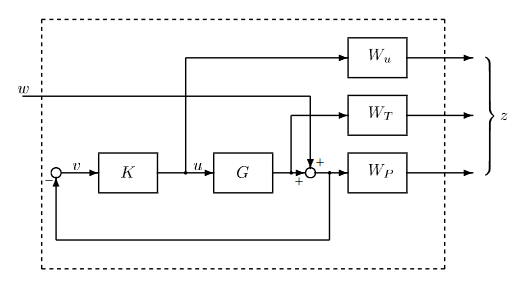

Diagram thanks to https://math.stackexchange.com/questions/2400110/how-do-i-find-detectable-and-stabilizable-states-in-robust-control

% We desire %O.S. < 5% and T_s(2%) <= 1 [s]
overshoot_c = 0.05;
T_s_c = 3;
epsilon_e_c = 1E-2;
overshoot_p = 0.01;
T_s_p = 1;
epsilon_e_p = 1E-2;

zeta_e_c = -log(overshoot_c) / sqrt(pi^2 + (log(overshoot_c))^2);
omega_n_e_c = -log(0.02) / (T_s_c * zeta_e_c);
zeta_e_p = -log(overshoot_p) / sqrt(pi^2 + (log(overshoot_p))^2);
omega_n_e_p = -log(0.02) / (T_s_p * zeta_e_p);

omega_b_e_c = omega_n_e_c / sqrt(2); % Zhou p. 90
alpha_e_c = sqrt(0.5 + 0.5 * sqrt(1 + 8*zeta_e_c^2)); % Zhou p. 90
M_s_e_c = alpha_e_c * sqrt(alpha_e_c^2 + 4 * zeta_e_c^2) / sqrt((1 - alpha_e_c^2)^2 + 4 * zeta_e_c^2 * alpha_e_c^2); % Zhou p. 90

omega_b_e_p = omega_n_e_p / sqrt(2); % Zhou p. 90
alpha_e_p = sqrt(0.5 + 0.5 * sqrt(1 + 8*zeta_e_p^2)); % Zhou p. 90
M_s_e_p = alpha_e_p * sqrt(alpha_e_p^2 + 4 * zeta_e_p^2) / sqrt((1 - alpha_e_p^2)^2 + 4 * zeta_e_p^2 * alpha_e_p^2); % Zhou p. 90


W_e = ss([tf([1/M_s_e_c, omega_b_e_c], [1, omega_b_e_c * epsilon_e_c]), 0; 0, tf([1/M_s_e_p, omega_b_e_p], [1, omega_b_e_p * epsilon_e_p])]); % Zhou Equation 6.6
W_e.Name = "Output Weighting Function";

W_e.InputName = {'x_c(t)', 'alpha(t)'};
W_e.InputUnit = {'m', 'rad'};

W_e.StateName = {'W_e_x_1', 'W_e_x_2'};
W_e.StateUnit = {'m', 'rad'};

W_e.OutputName = {'x_c_tilde(t)', 'alpha_tilde(t)'};
W_e.OutputUnit = {'m', 'rad'};

% The servomotor cannot operate at more than 5 volts at frequencies greather than 50 Hz
M_u = 5;
omega_bc_u = 2*pi*50 / 10;
epsilon_u = 1E-2;
W_u = tf([1,omega_bc_u / M_u], [epsilon_u, omega_bc_u]);  % Zhou Equation 6.9
W_u = ss(W_u);
W_u.Name = "Input Weighting Function";

W_u.InputName = 'V_m(t)';
W_u.InputUnit = 'V';

W_u.StateName = 'W_u_x_1';
W_u.StateUnit = 'V';

W_u.OutputName = 'V_m_tilde(t)';
W_u.OutputUnit = 'V';

connected_system = connect(unc_sys, W_e, W_u, {'F_d(t)', 'Tau_d(t)', 'V_m(t)'}, {'V_m_tilde(t)', 'x_c_tilde(t)', 'alpha_tilde(t)', 'x_c(t)', 'alpha(t)'});
connected_system.Name = "Connected Uncertain System";
[K, CL, gamma] = hinfsyn(connected_system.NominalValue, 2, 1);

Controllability_connected_system = ctrb(connected_system.NominalValue.A, connected_system.NominalValue.B);
if rank(Controllability_connected_system) == length(x(t))
    disp("[✔] System is controllable.");
else
    warning("[❌] System is NOT controllable.");
end

Observability_connected_system = obsv(connected_system.NominalValue.A, connected_system.NominalValue.C);
if rank(Observability_connected_system) == length(x(t))
    disp("[✔] System is observable.");
else
    warning("[❌] System is NOT observable.");
end

# Helper Functions

These heper functions reduce the amount of code in the previous sections. They make it a lot easier to read the code in the previous sections, or overall just help improve the program.

% Mix between the `functionalDerivative` and the `jacobian` symbolic methods.

function output = functionalJacobian(f, x, y)
    symbols = sym("s", size(y));
    variables = subs(x, y, symbols);
    functions = subs(f, y, symbols);
    tmp = jacobian(functions, variables);
    output = subs(tmp, symbols, y);
end

% Simultaneous `simplify` and `collect`. 1st parameter is the function we  is 
% the function we want to simplify. 2nd parameter is the parameters for 
% `collect`. 3rd parameter is the amount of steps for simplification. 4th
% parameter is the amount of seconds allocated for simplification.
function output = enhancedSimplify(varargin)
    steps = 10;
    seconds = 5;

    if nargin >= 3
        steps = varargin{3};
    end
    if nargin >= 4
        seconds = varargin{4};
    end
   
    output = simplify( ...
        varargin{1}, ...
        "IgnoreAnalyticConstraints", true, ...
        "Criterion", "preferReal", ...
        "Steps", steps, ...
        "Seconds", seconds ...
    );
    
    output = collect(output, varargin{2});
end

% Reshape a matrix. Helps prevent some problems introduced by the
% `transpose` function
function output = row2col(row)
    output = reshape(row, [], 1);
end